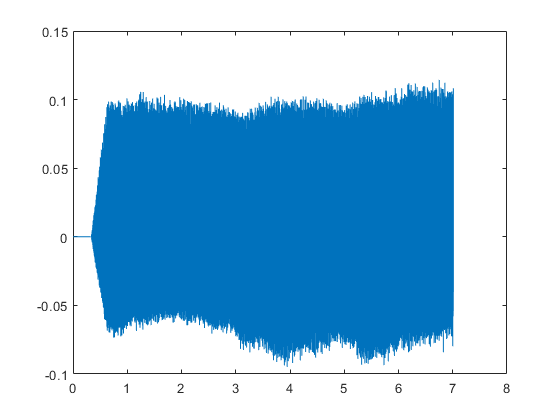

clear;

[y,fs]=audioread('pasco_audio.m4a');
t=[1:length(y)]/fs -1/fs;% times in s starting at 0
plot(t,y);

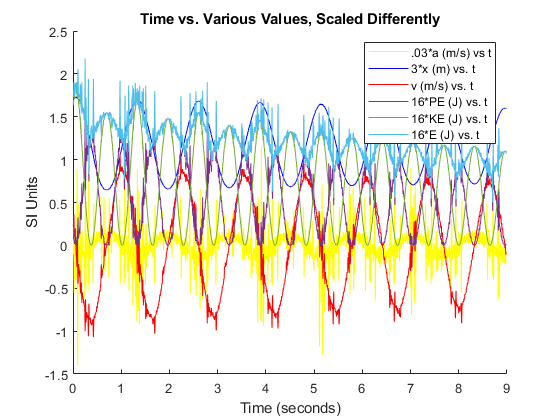


importscript
figure; hold on;
xlabel("Time (seconds)")
ylabel("SI Units")
title("Time vs. Various Values, Scaled Differently")

plot(Times, .03*Accelerationms, 'Color','Yellow');
plot(Times, 3*Positionm, 'Color', 'Blue');
plot(Times, Velocityms, 'Color', 'Red');

xmean = mean(Positionm);
m = .2015;
k = 6.47;

PE = .5*m*Velocityms.^2;
KE = .5*k*(Positionm-xmean).^2;
E = PE + KE;

plot(Times, 16*PE);
plot(Times, 16*KE);
plot(Times, 16*E);

legend('.03*a (m/s) vs t', '3*x (m) vs. t', 'v (m/s) vs. t', '16*PE (J) vs. t', '16*KE (J) vs. t', '16*E (J) vs. t');


hold off